# Offline RL for GBWM — Week 7.0: Stress Flag in State (binary, 7D)

Week 6.1 produced the first regime-conditional policy of the project — five actions diverged >=5pp between stress and normal test days. But the conditioning direction was counterintuitive: in stress the agent went MORE aggressive (#9/#13/#14/#15), in normal it defended (#11/#1/#2). Diagnosis: in train data every stress event (including COVID 2020) was followed by a sharp recovery, so the gated drawdown penalty net-rewarded aggressive behavior in stress; and test "stress" labels in 2022-2024 fire heavily on AI-rally days where stocks were rising despite high VIX.

7.0 hypothesis: the indirect reward-shaping conditioning is the bottleneck. By putting the stress flag DIRECTLY into the state vector, the network can condition its Q estimate explicitly on regime rather than inferring it from macro z-scores through the reward signal alone. This should give the agent a cleaner inductive bias toward "act differently in stress".

Everything else identical to 6.1 (extended train, uniform sampling, regime-gated beta reward, same network/agent/eval) so the only changed variable is the state vector.

Decision rule after running: if 7.0 improves both worst Sharpe AND flips the action-split direction toward defensive-on-stress, this is the Week 7 deliverable and we proceed to 7.0b (continuous stressScore). If 7.0 shows no Q-gap (network ignored the 7th dim) or regresses, abandon state- extension and move to backtesting / MSP baseline.

clear; clc;

## Fixed Parameters (identical to 6.1)

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 3020;
horizonPeriods  = 30;
numEpisodes     = 200;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week7_0_state_stress");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% Regime-gated drawdown penalty (kept from 6.1)
BETA_HIGH = 8.0;
BETA_LOW  = 2.0;
DD_THR    = 0.03;

% Stress gate thresholds
VIX_THR_Z   =  1.5;
SLOPE_THR_Z = -1.5;

% Macro column indices in z-scored matrix [DGS10_z, T10Y2Y_z, VIXCLS_z, DFF_z]
COL_T10Y2Y = 2;
COL_VIX    = 3;

% Q-gap diagnostic sample size
QGAP_NSAMPLES = 300;

## Load EXTENDED price data

pricesTT   = readtable("data/prices_train_extended.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load EXTENDED macro, z-score on extended train

macroTT   = readtable("data/macro_train_extended.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Stress flags (train and test) — now used for BOTH reward gate AND state input

isStressDay_train = (M_train_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_train_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
trainStressRate   = mean(isStressDay_train(1:trainingRange));

isStressDay_test  = (M_test_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_test_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
testStressRate    = mean(isStressDay_test);

% NEW: convenience function for appending the stress dim
stressFlagOf = @(isStressVec, dayIdx) double(isStressVec(dayIdx));

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

% NEW: obsDim grows by 1 to include the binary stress flag
obsDim = 2 + size(M_train_z, 2) + 1;   % was 2 + 4 in 6.1, now 7

fprintf("=== Week 7.0 setup (binary stress flag in state) ===\n");

=== Week 7.0 setup (binary stress flag in state) ===


fprintf("  Observation dim    : %d  (6 -> 7, appended binary stress flag)\n", obsDim);

  Observation dim    : 7  (6 -> 7, appended binary stress flag)


fprintf("  Stress in state    : true\n");

  Stress in state    : true


fprintf("  Stress thresholds  : VIX_z > %.1f  OR  T10Y2Y_z < %.1f\n", ...
    VIX_THR_Z, SLOPE_THR_Z);

  Stress thresholds  : VIX_z > 1.5  OR  T10Y2Y_z < -1.5


fprintf("  Train stress rate  : %.1f%%\n", 100 * trainStressRate);

  Train stress rate  : 11.0%


fprintf("  Test  stress rate  : %.1f%%\n", 100 * testStressRate);

  Test  stress rate  : 67.7%


fprintf("  Reward gate (kept) : beta = %.1f (stress)  /  %.1f (normal)\n", ...
    BETA_HIGH, BETA_LOW);

  Reward gate (kept) : beta = 8.0 (stress)  /  2.0 (normal)


## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.actionHistStress = zeros(nSeeds, numActions);
results.actionHistNormal = zeros(nSeeds, numActions);
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenaltyHigh = nan(nSeeds, 1);
results.meanPenaltyLow  = nan(nSeeds, 1);
results.qGapMean        = nan(nSeeds, 1);   % NEW: |Q(stress=1) - Q(stress=0)|
results.qGapMaxAction   = nan(nSeeds, 1);   % NEW: largest per-action Q gap

allWealthPathsBySeed = cell(nSeeds, 1);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Uniform sliding start (no oversampling)
    stepSize      = max(1, floor((trainingRange - horizonPeriods) / numEpisodes));
    sampledStarts = (1 + (0:numEpisodes-1)' * stepSize);
    sampledStarts = sampledStarts(sampledStarts + horizonPeriods - 1 <= trainingRange);
    nEpThisSeed   = numel(sampledStarts);

    % --- Build offline episodes with regime-gated drawdown reward + 7D obs
    nPenaltyStepsHigh = 0;
    nPenaltyStepsLow  = 0;
    penaltySumHigh    = 0;
    penaltySumLow     = 0;
    sanityChecked     = false;

    % Collect non-stress training obs for the Q-gap diagnostic (we copy them
    % later and flip the 7th dim to 1 to measure how much the network reacts)
    qGapPool = nan(obsDim, 0);

    for episodeCount = 1:nEpThisSeed
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); ...
                        timeFrac(t); ...
                        macroVec; ...
                        stressFlagOf(isStressDay_train, dayIdx)];

            if ~sanityChecked
                assert(numel(obs) == obsDim, "Obs dim mismatch (got %d, expected %d)", ...
                    numel(obs), obsDim);
                fprintf("  Sanity: first obs has %d elements (expected %d) — OK\n", ...
                    numel(obs), obsDim);
                sanityChecked = true;
            end

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % Regime-gated penalty (unchanged from 6.1)
            stressFlag = isStressDay_train(dayIdx);
            betaT      = BETA_HIGH * stressFlag + BETA_LOW * ~stressFlag;

            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = betaT * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                if stressFlag
                    nPenaltyStepsHigh = nPenaltyStepsHigh + 1;
                    penaltySumHigh    = penaltySumHigh + penalty;
                else
                    nPenaltyStepsLow  = nPenaltyStepsLow + 1;
                    penaltySumLow     = penaltySumLow + penalty;
                end
            end

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec; ...
                            stressFlagOf(isStressDay_train, nextDayIdx)];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            % Reservoir-style cheap collection of non-stress obs for Q-gap
            if ~stressFlag && size(qGapPool, 2) < QGAP_NSAMPLES
                qGapPool(:, end+1) = obs; %#ok<SAGROW>
            end

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = nEpThisSeed * horizonPeriods;
    nPenaltyAll = nPenaltyStepsHigh + nPenaltyStepsLow;
    results.penaltyShare(sIdx)    = nPenaltyAll / totalSteps;
    if nPenaltyStepsHigh > 0
        results.meanPenaltyHigh(sIdx) = penaltySumHigh / nPenaltyStepsHigh;
    else
        results.meanPenaltyHigh(sIdx) = 0;
    end
    if nPenaltyStepsLow > 0
        results.meanPenaltyLow(sIdx) = penaltySumLow / nPenaltyStepsLow;
    else
        results.meanPenaltyLow(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d steps). Penalty: stress %d (avg %.4f) / normal %d (avg %.4f)\n", ...
        nEpThisSeed, totalSteps, ...
        nPenaltyStepsHigh, results.meanPenaltyHigh(sIdx), ...
        nPenaltyStepsLow, results.meanPenaltyLow(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent (7D input) ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Q-gap diagnostic: does the network actually USE the stress flag? ---
    if size(qGapPool, 2) > 0
        trainedCritic = getCritic(agent);
        sampleObs0 = qGapPool;                  % all have stress=0 by construction
        sampleObs1 = sampleObs0;
        sampleObs1(end, :) = 1;                 % flip the 7th dim to 1

        nSamp = size(sampleObs0, 2);
        Q0 = nan(numActions, nSamp);
        Q1 = nan(numActions, nSamp);
        for k = 1:nSamp
            Q0(:, k) = getValue(trainedCritic, {sampleObs0(:, k)});
            Q1(:, k) = getValue(trainedCritic, {sampleObs1(:, k)});
        end
        qGapAbs   = abs(Q1 - Q0);                 % numActions x nSamp
        results.qGapMean(sIdx)      = mean(qGapAbs, 'all');
        results.qGapMaxAction(sIdx) = max(mean(qGapAbs, 2));   % worst action

        fprintf("  Q-gap diagnostic (%d samples, stress 0->1): mean %.4f | max-per-action %.4f\n", ...
            nSamp, results.qGapMean(sIdx), results.qGapMaxAction(sIdx));
    else
        fprintf("  Q-gap diagnostic skipped (no non-stress samples collected)\n");
    end

    % --- Hold-out evaluation (7D obs) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);
    allActionStressFlag = false(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); ...
                          timeFrac(t); ...
                          macroVec; ...
                          stressFlagOf(isStressDay_test, dayIdx)] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            allActionStressFlag(ep, t) = isStressDay_test(dayIdx);
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);

    flatActions = allActions(:);
    flatStress  = allActionStressFlag(:);
    for a = 1:numActions
        results.actionHist(sIdx, a)        = sum(flatActions == a);
        results.actionHistStress(sIdx, a)  = sum(flatActions == a &  flatStress);
        results.actionHistNormal(sIdx, a)  = sum(flatActions == a & ~flatStress);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Sanity: first obs has 7 elements (expected 7) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.3989) / normal 1071 (avg 0.0544)


  Q-gap diagnostic (300 samples, stress 0->1): mean 0.4133 | max-per-action 0.5355


  Success 11/30 | Sharpe 0.21±3.41 | MaxDD 7.39%±5.18% | TermW 100036 (P10 91613)



========== Seed 2000 (2/5) ==========


  Sanity: first obs has 7 elements (expected 7) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 301 (avg 0.4709) / normal 1170 (avg 0.0547)


  Q-gap diagnostic (300 samples, stress 0->1): mean 0.4367 | max-per-action 0.7249


  Success 16/30 | Sharpe 0.94±2.56 | MaxDD 8.49%±6.48% | TermW 101974 (P10 92788)



========== Seed 3000 (3/5) ==========


  Sanity: first obs has 7 elements (expected 7) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 329 (avg 0.4201) / normal 1241 (avg 0.0592)


  Q-gap diagnostic (300 samples, stress 0->1): mean 3.4357 | max-per-action 4.1928


  Success 15/30 | Sharpe 1.07±3.25 | MaxDD 10.20%±6.24% | TermW 103119 (P10 91325)



========== Seed 4000 (4/5) ==========


  Sanity: first obs has 7 elements (expected 7) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 325 (avg 0.3331) / normal 1298 (avg 0.0612)


  Q-gap diagnostic (300 samples, stress 0->1): mean 6.6696 | max-per-action 7.4773


  Success 17/30 | Sharpe 0.72±2.91 | MaxDD 8.66%±6.11% | TermW 101436 (P10 89684)



========== Seed 5000 (5/5) ==========


  Sanity: first obs has 7 elements (expected 7) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.4701) / normal 1092 (avg 0.0526)


  Q-gap diagnostic (300 samples, stress 0->1): mean 0.2318 | max-per-action 0.3666


  Success 9/30 | Sharpe -0.25±3.37 | MaxDD 7.28%±6.06% | TermW 98464 (P10 91527)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 7.0 stress flag in state (7D) =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 7.0 stress flag in state (7D) =====


fprintf("Train range          : 2010-01 -> 2021-12  (%d days)\n", trainingRange);

Train range          : 2010-01 -> 2021-12  (3020 days)


fprintf("State dim            : %d  (binary stress flag appended)\n", obsDim);

State dim            : 7  (binary stress flag appended)


fprintf("Reward gate (kept)   : beta = %.1f (stress) / %.1f (normal)   DD_THR = %.3f\n", ...
    BETA_HIGH, BETA_LOW, DD_THR);

Reward gate (kept)   : beta = 8.0 (stress) / 2.0 (normal)   DD_THR = 0.030


fprintf("Penalty-active share : %.1f%% of training steps (avg)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share : 25.0% of training steps (avg)


fprintf("Penalty avg magn     : stress %.4f  /  normal %.4f   (6.1 baseline: 0.4186 / 0.0564)\n", ...
    mean(results.meanPenaltyHigh), mean(results.meanPenaltyLow));

Penalty avg magn     : stress 0.4186  /  normal 0.0564   (6.1 baseline: 0.4186 / 0.0564)


fprintf("Q-gap (state effect) : mean %.4f  |  max-per-action %.4f   (0 = network ignored stress dim)\n", ...
    mean(results.qGapMean, 'omitnan'), mean(results.qGapMaxAction, 'omitnan'));

Q-gap (state effect) : mean 2.2374  |  max-per-action 2.6594   (0 = network ignored stress dim)


fprintf("Success rate         : %.1f / %d  (std %.2f)   <-- 6.1: 14.6\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 13.6 / 30  (std 3.44)   <-- 6.1: 14.6


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)   <-- 6.1: 0.66 (std 0.23)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.54 (across-seed std 0.55)   <-- 6.1: 0.66 (std 0.23)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 3.10 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)   <-- 6.1: 7.78%%\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 8.40% (across-seed std 1.18%)   <-- 6.1: 7.78%


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)   <-- 6.1: 101633 (std 1690)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 101006 (across-seed std 1802)   <-- 6.1: 101633 (std 1690)


fprintf("Terminal P10 (avg)   : %.0f   <-- 6.1: 89758\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 91387   <-- 6.1: 89758


fprintf("Worst Sharpe (avg)   : %.2f   <-- 6.1: -6.37 | Plan C: -5.38\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)   : -6.87   <-- 6.1: -6.37 | Plan C: -5.38


fprintf("MaxDD P90 (avg)      : %.2f%%   <-- 6.1: 15.75%% | Plan C: 11.79%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 16.88%   <-- 6.1: 15.75% | Plan C: 11.79%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | Q-gap\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | Q-gap


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f | %.4f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        results.qGapMean(sIdx));
end

1000 |   11 |  0.21 ± 3.41    |  7.39% ± 5.18%  | 100036 / 91613 | 0.4133
2000 |   16 |  0.94 ± 2.56    |  8.49% ± 6.48%  | 101974 / 92788 | 0.4367
3000 |   15 |  1.07 ± 3.25    | 10.20% ± 6.24%  | 103119 / 91325 | 3.4357
4000 |   17 |  0.72 ± 2.91    |  8.66% ± 6.11%  | 101436 / 89684 | 6.6696
5000 |    9 | -0.25 ± 3.37    |  7.28% ± 6.06%  | 98464 / 91527 | 0.2318



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :  243 (5.4%)
  action  2 :  311 (6.9%)
  action  3 :  131 (2.9%)
  action  4 :    4 (0.1%)
  action  5 :  111 (2.5%)
  action  6 :   98 (2.2%)
  action  7 :  101 (2.2%)
  action  8 :   15 (0.3%)
  action  9 :  508 (11.3%)
  action 10 :  509 (11.3%)
  action 11 :   34 (0.8%)
  action 12 : 1393 (31.0%)
  action 13 :  762 (16.9%)
  action 14 :  213 (4.7%)
  action 15 :   67 (1.5%)



% Core diagnostic — stress vs normal action split (compare directly to 6.1)
fprintf("\n--- Action histogram split by TEST regime (vs 6.1 the make-or-break check) ---\n");


--- Action histogram split by TEST regime (vs 6.1 the make-or-break check) ---


totalStress = sum(results.actionHistStress, 1);
totalNormal = sum(results.actionHistNormal, 1);
sumS = sum(totalStress); sumN = sum(totalNormal);
fprintf("action |  stress%%  |  normal%%  |  diff (pp)\n");

action |  stress%  |  normal%  |  diff (pp)


for a = 1:numActions
    if totalStress(a) + totalNormal(a) > 0
        pS = 100 * totalStress(a) / max(sumS, 1);
        pN = 100 * totalNormal(a) / max(sumN, 1);
        marker = "";
        if abs(pS - pN) >= 5
            marker = "  <-- diverges";
        end
        fprintf("  %2d   |  %5.1f    |  %5.1f    |  %+5.1f%s\n", ...
            a, pS, pN, pS - pN, marker);
    end
end

   1   |    7.1    |    0.3    |   +6.8  <-- diverges
   2   |    9.2    |    0.0    |   +9.2  <-- diverges
   3   |    2.9    |    3.1    |   -0.2
   4   |    0.1    |    0.1    |   -0.0
   5   |    2.3    |    3.1    |   -0.8
   6   |    2.0    |    2.7    |   -0.7
   7   |    0.2    |    8.4    |   -8.2  <-- diverges
   8   |    0.1    |    1.1    |   -1.0
   9   |   10.3    |   14.5    |   -4.2
  10   |    8.2    |   20.8    |  -12.6  <-- diverges
  11   |    0.7    |    0.8    |   -0.1
  12   |   35.6    |   16.6    |  +19.1  <-- diverges
  13   |   17.6    |   14.8    |   +2.8
  14   |    2.4    |   11.9    |   -9.4  <-- diverges
  15   |    1.4    |    1.9    |   -0.5



fprintf("\nInterpretation hints:\n");


Interpretation hints:


fprintf("  - 6.1 was counterintuitive: stress -> aggressive (#9/#13/#14/#15)\n");

  - 6.1 was counterintuitive: stress -> aggressive (#9/#13/#14/#15)


fprintf("  - 7.0 ideal: stress -> defensive (#1/#2/#3/#11), normal -> aggressive\n");

  - 7.0 ideal: stress -> defensive (#1/#2/#3/#11), normal -> aggressive


fprintf("  - If Q-gap < 0.01, the network ignored the 7th dim entirely\n");

  - If Q-gap < 0.01, the network ignored the 7th dim entirely


## Plot — aggregated wealth band across all seeds

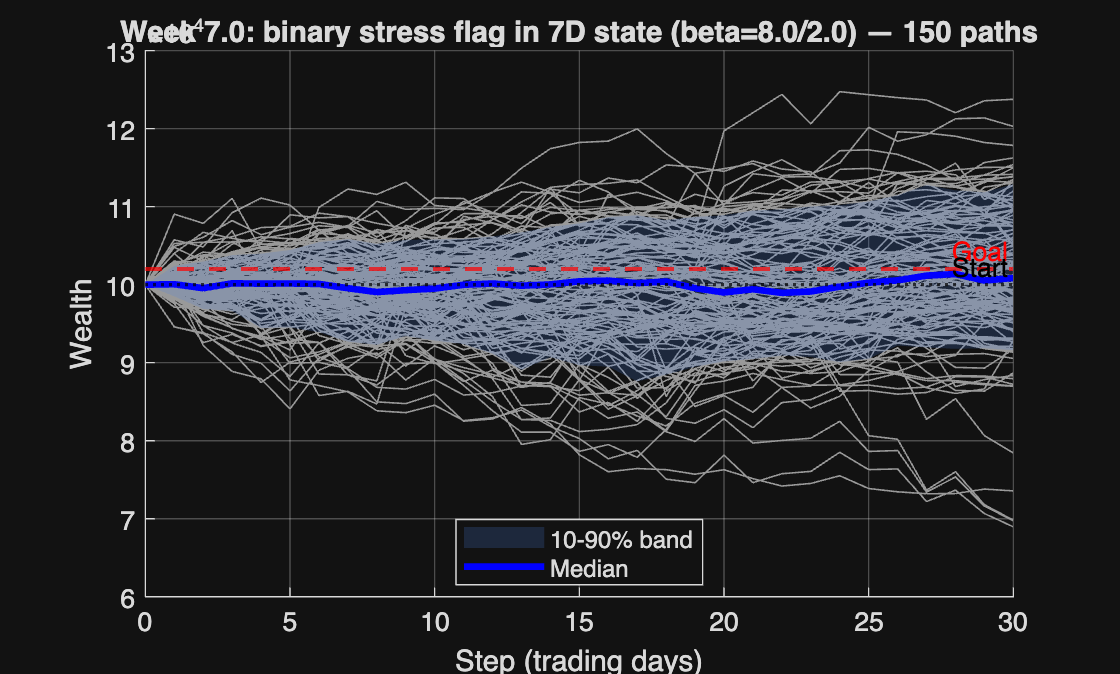

figure('Name','Hold-out wealth paths (Week 7.0 stress flag in 7D state)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 7.0: binary stress flag in 7D state (beta=%.1f/%.1f) — %d paths', ...
    BETA_HIGH, BETA_LOW, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end